Let's create a diffuse-porous xylem network

rowNb = 50;
colNb = 10;
depNb = 50;
Pc = [0.75 0.75];
NPc = [0.75 0.75];
Pe_rad = [0.9 0.9];
Pe_tan = [0.02 0.02];
radDist = [1 1 1  0.1 0.1 0.1 0.1 0.1 0.1 0.01];
Lce = 2.88e-3;
Dc = 24.6e-6;
Dc_cv = 0.12;
Dp = 32.0e-9;
Dm = 6.3e-6;
A = 16;
B = 4;
fc = 0.31;
fpf = 0.7;
fap = 0.06;
e_mean = 0.02;
e_cv = 0.35;
Tm = 234e-9;
Lp = 654e-9;
ASPcalcmethod = 'Pore';
sim = XylemNet(rowNb,colNb,depNb,Pc,NPc,Pe_rad,Pe_tan,radDist, Lce,Dc,Dc_cv,Dp,Dm,A,B,fc,fpf,fap,...
      e_mean,e_cv,Tm,Lp,ASPcalcmethod);

The Matlab function 'moment' gives central moments, to convert these to the regular first and second order moments:

m1 = mc1 + mean, where m1 is the regular first moment

mc2 = integral[(x - mean)^2 PDF(x), {x, 0, inf}] = m2 - 2*mean*m1 + mean^2. So, m2 = mc2 + 2*mean*m1 - mean^2

degArr = degree(sim.gCav);
mdegree = mean(degArr)

mdegree = 2.4361

m1 = moment(degArr,1) + mdegree

m1 = 2.4361

m2 = moment(degArr,2) + 2*mdegree*m1 - mdegree^2

m2 = 6.8921

The bond percolation threshold is given by the following equation following chapter 16 of Newman

percThresh = m1/(m2-m1)

percThresh = 0.5467

We expect a fraction of "occupied" nodes equal to percThresh so a giant percolation cluster will appear and cause real damage to the xylem

The VC of the 'sim' network is (from the VCGen.m script)

jt = 10;
stepSize = 0.3; %MPa
itmax = 15; 
inEmb = 1; 
AvgBool = false;

[mVC.PLC,mVC.PV,mVC.Pressures,mVC.Kmax,mVC.Kini,mVC.voltot,mVC.embNb,...
    mVC.ncNb,Emb,Pen] = cavitation_process(sim,jt,stepSize,itmax,inEmb,...
    AvgBool);


## Let's compute the giant percolation cluster from a bond percolation problem

We extract the degree distribution

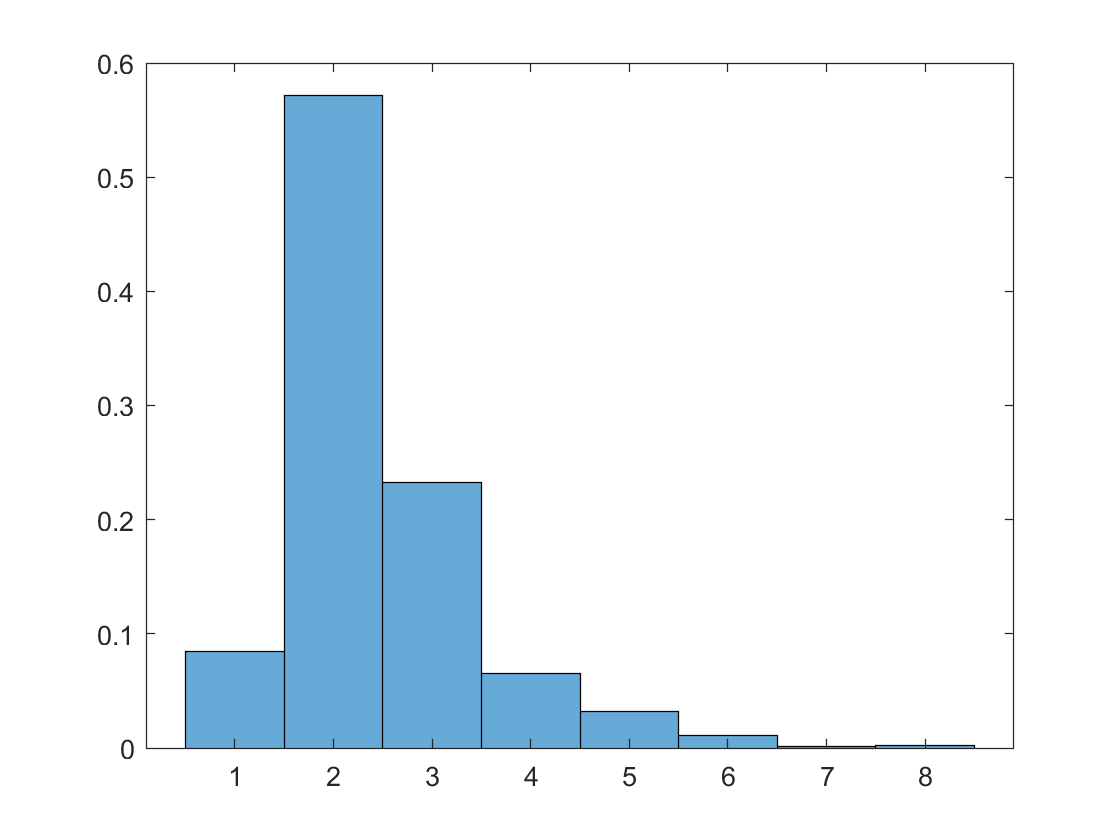

h =   Histogram with properties:

             Data: [908×1 double]
           Values: [0.0848 0.5716 0.2324 0.0650 0.0319 0.0110 0.0011 0.0022]
          NumBins: 8
         BinEdges: [0.5000 1.5000 2.5000 3.5000 4.5000 5.5000 6.5000 7.5000 8.5000]
         BinWidth: 1
        BinLimits: [0.5000 8.5000]
    Normalization: 'probability'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


h=histogram(degree(sim.gCav),'Normalization',"probability")

sum(h.Values .* (h.BinEdges(1:end-1) + 0.5))

ans = 2.4361


g0_prime(1,[0 h.Values])

ans = 2.4361


vals = [0 h.Values];
phi_range = percThresh+0.02 : 0.02 : 0.95;
us = zeros(1,length(phi_range));
Ss = zeros(1,length(phi_range));
ind = 1;
for phi = phi_range
    fun = @(u) find_u(u,vals, phi);
    [us(ind),~,ef,~] = fzero(fun,0.2);
    if ef ~= 1
        us(ind) = 1;
    end
    Ss(ind) = 1 - g0(us(ind), vals);
    ind = ind + 1;
end


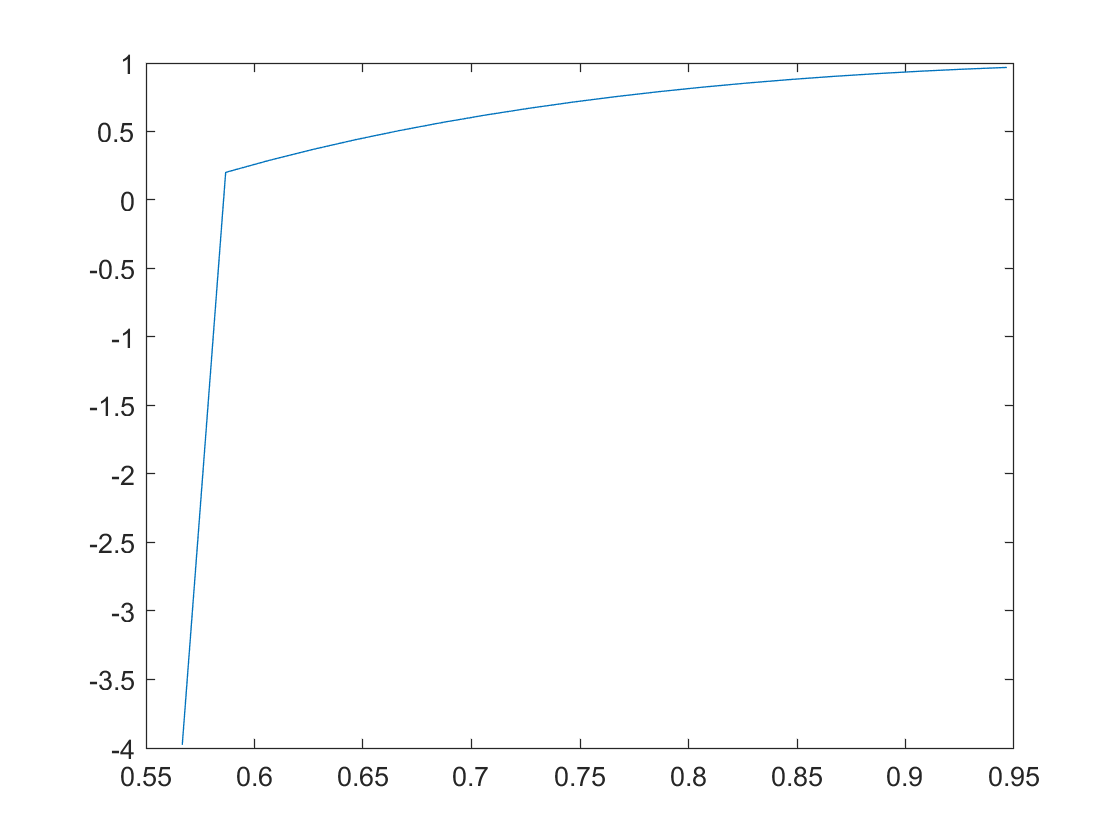

plot(phi_range, Ss)

Here, take the distribution of ASPs into account

hASPCDF = histogram(sim.gCav.Edges{:,'Weight'},...
    'Normalization',"cdf");
%Check if histogram values for the CDF have duplicate elements which will
%cause the interpolation code to generate an error.
if length(hASPCDF.Values) > length(unique(hASPCDF.Values))
    hValDup = true;
    while hValDup
        hASPCDF.fewerbins;
        hValDup = false;
        if length(hASPCDF.Values) > length(unique(hASPCDF.Values))
            hValDup = true;
        end
    end
end
hASPCDF

hASPCDF =   Histogram with properties:

             Data: [1106×1 double]
           Values: [0.0018 0.0081 0.0226 0.0597 0.1031 0.1754 0.2595 0.3662 0.4810 0.6103 0.7025 0.7939 0.8535 0.8987 0.9286 0.9584 0.9783 0.9855 0.9919 0.9964 0.9991 1]
          NumBins: 22
         BinEdges: [0.2000 0.4000 0.6000 0.8000 1 1.2000 1.4000 1.6000 1.8000 2 2.2000 2.4000 2.6000 2.8000 3.0000 3.2000 3.4000 3.6000 3.8000 4 4.2000 4.4000 4.6000]
         BinWidth: 0.2000
        BinLimits: [0.2000 4.6000]
    Normalization: 'cdf'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


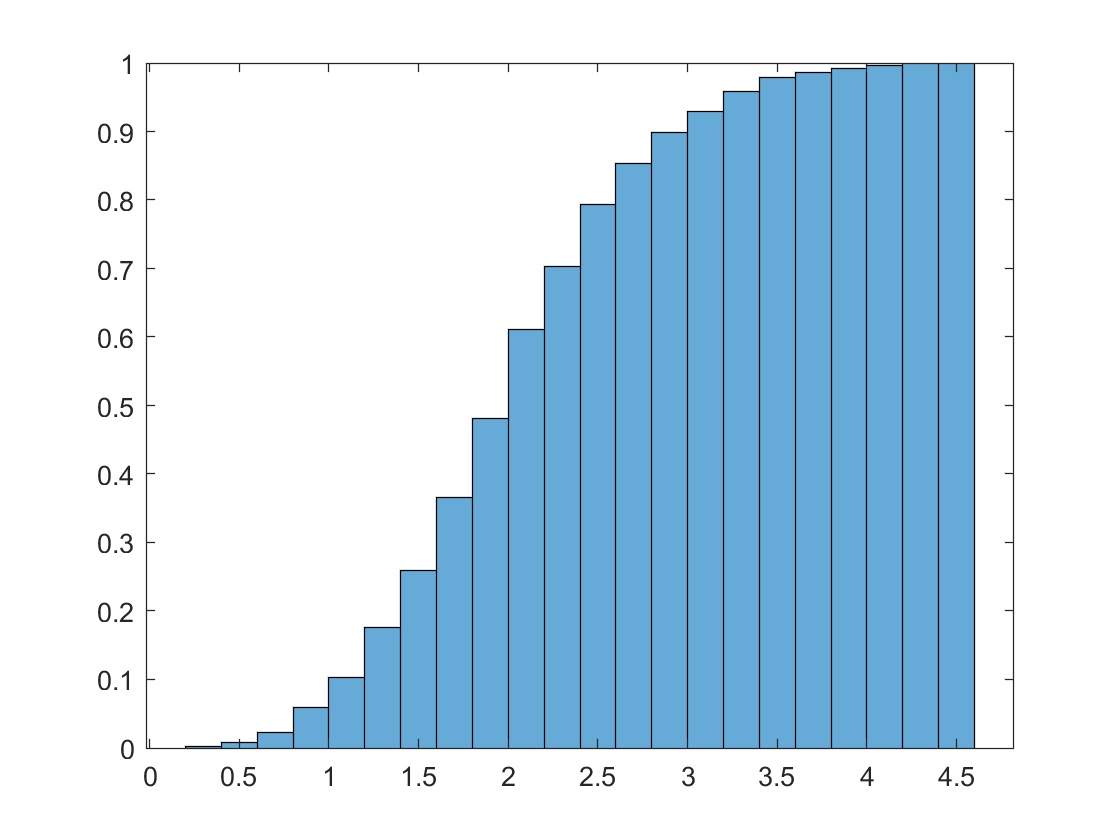

phi_to_P = interp1(hASPCDF.Values,...
    hASPCDF.BinEdges(1:end-1)+hASPCDF.BinWidth/2, phi_range,...
    'spline');
hold off

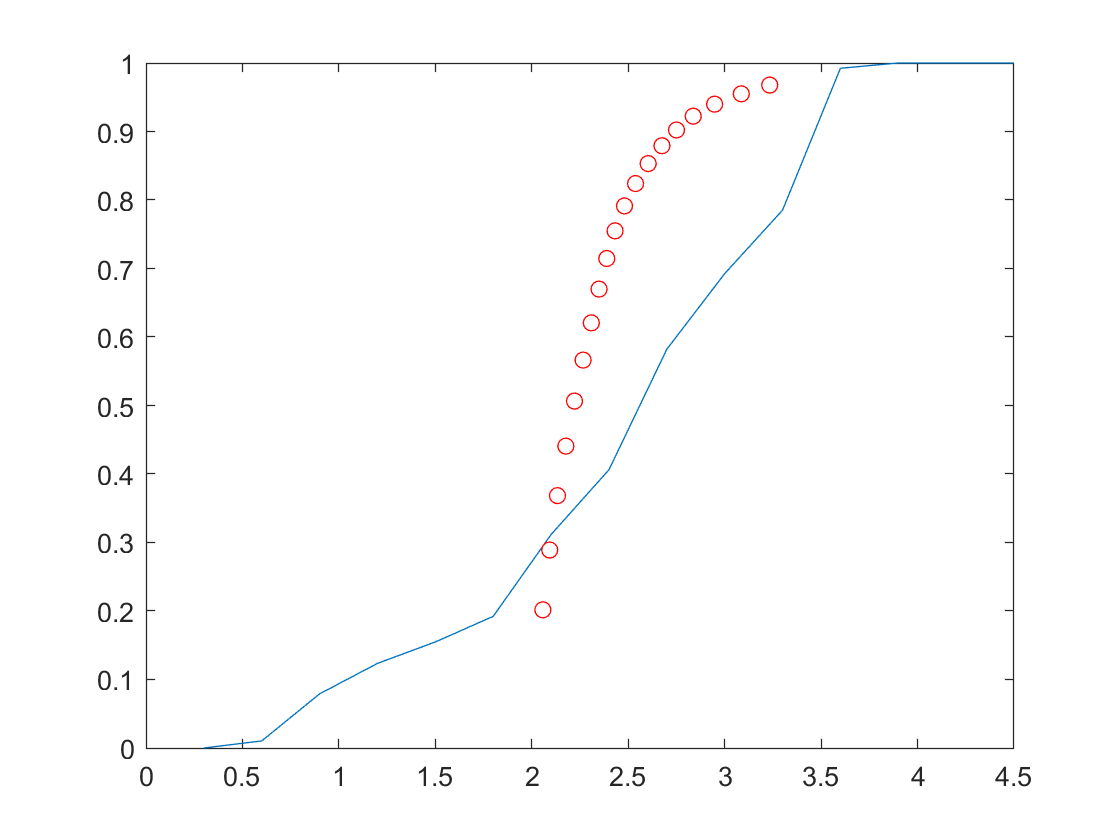

plot(mVC.Pressures, mVC.PLC)
hold on
plot(phi_to_P(2:end), Ss(2:end), 'ro')

Now, let's extract P12, P50, and P88 from the generated VC.

Find the last occurrence of of 0 PLC and first occurrence of 1 PLC

zeroLast = find(mVC.PLC == 0,1,'last');
oneFirst = find(mVC.PLC == 1,1,'first');

P12 = interp1(mVC.PLC(zeroLast:oneFirst),...
    mVC.Pressures(zeroLast:oneFirst), 0.12,...
    'linear')

P12 = 1.1763

P50 = interp1(mVC.PLC(zeroLast:oneFirst),...
    mVC.Pressures(zeroLast:oneFirst), 0.5,...
    'linear')

P50 = 2.5600

P88 = interp1(mVC.PLC(zeroLast:oneFirst),...
    mVC.Pressures(zeroLast:oneFirst), 0.88,...
    'linear')

P88 = 3.4373

Function definitions:

function g0_val = g0(x,vals)
    k = 0 : length(vals) - 1;
    g0_val = sum((vals(k+1).*x.^k));
end

function g0prime_val = g0_prime(x,vals)
    k = 0 : length(vals) - 1;
    g0prime_val = sum((k.*vals(k+1).*x.^(k-1)));
end

function g1_val = g1(x,vals)
    g1_val = g0_prime(x,vals)/g0_prime(1,vals);   
end

function res = find_u(u, vals, phi)
    res = u - 1 + phi - phi * g1(u, vals);
end

